threshold_dist_1 = 0.3154

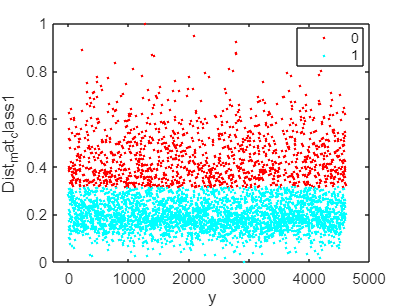

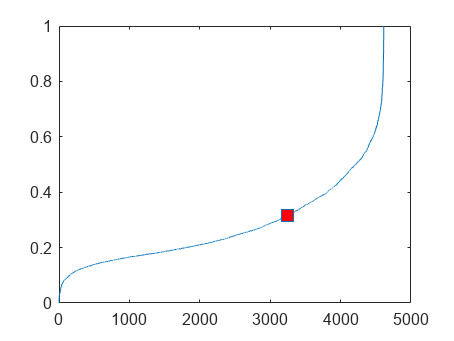

r1 = 1363

threshold_dist_7 = 0.5173

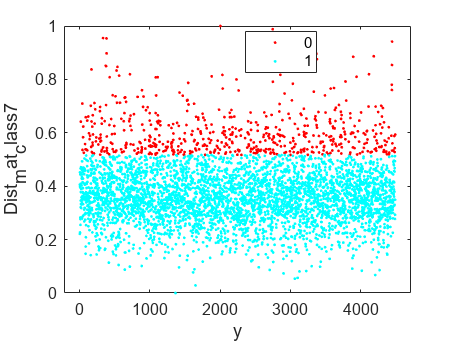

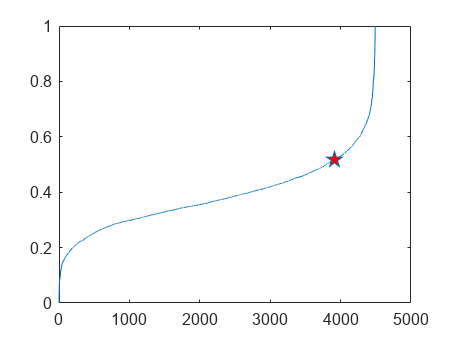

r7 = 579

threshold_dist_1 = 0.3442

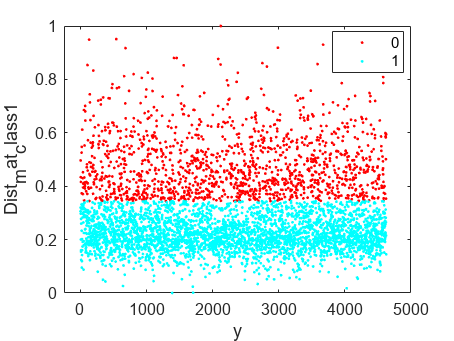

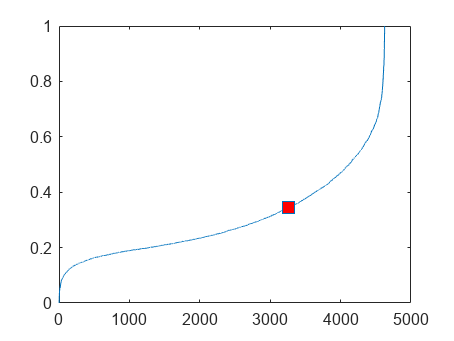

r1 = 1361

threshold_dist_7 = 0.4862

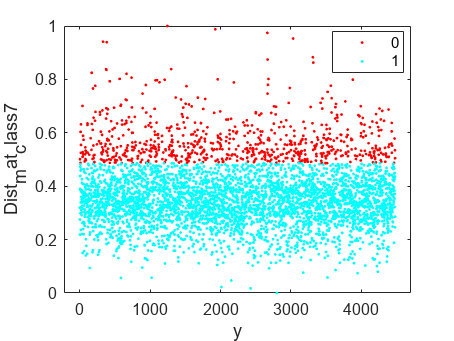

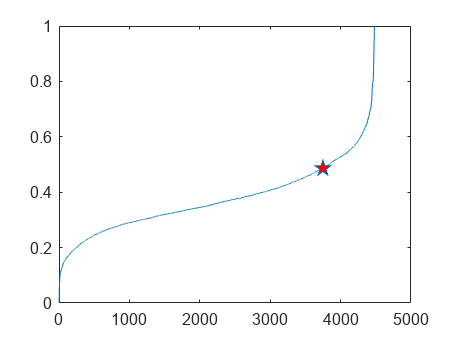

r7 = 731

threshold_dist_1 = 0.2996

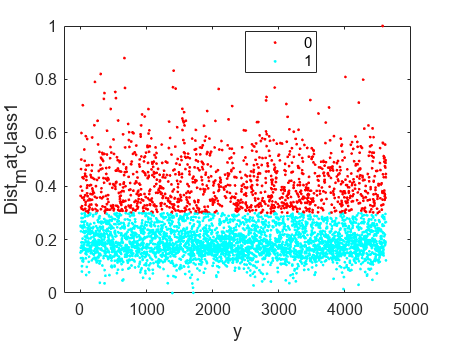

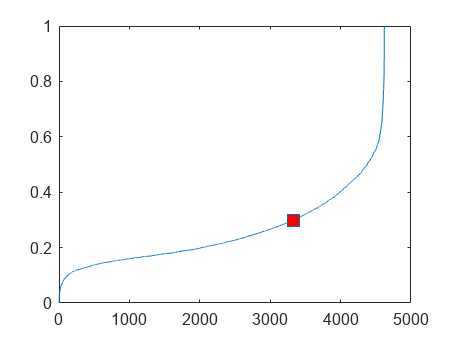

r1 = 1285

threshold_dist_7 = 0.4842

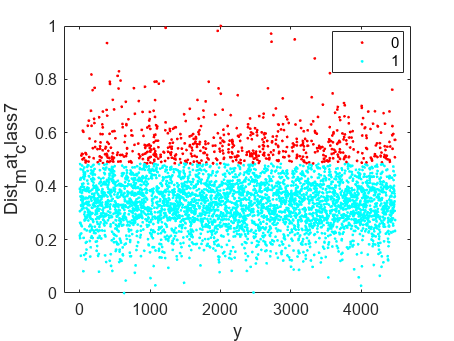

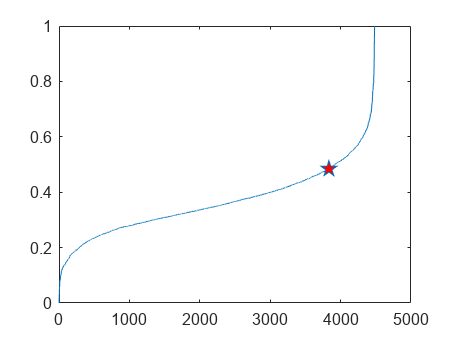

r7 = 650

threshold_dist_1 = 0.3210

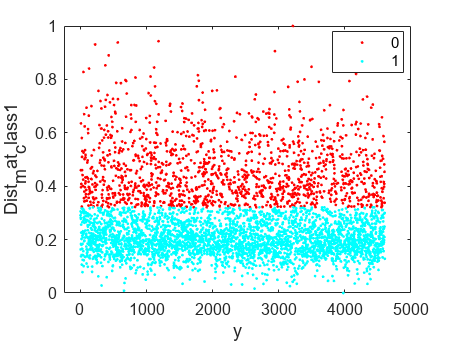

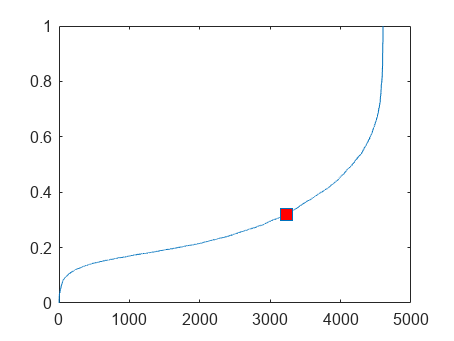

r1 = 1378

threshold_dist_7 = 0.4969

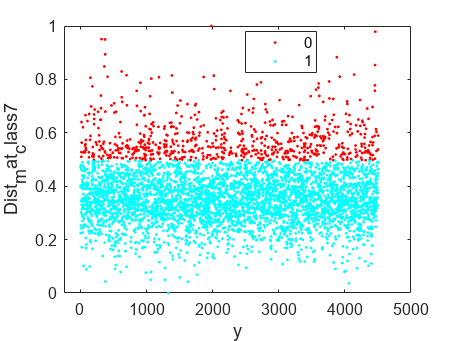

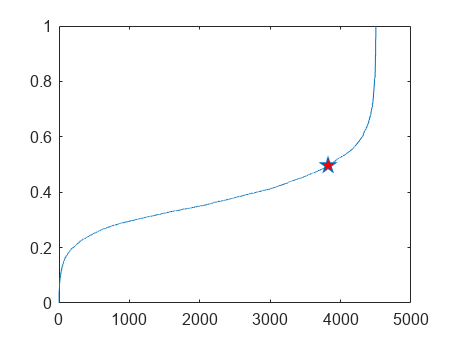

r7 = 680

threshold_dist_1 = 0.2710

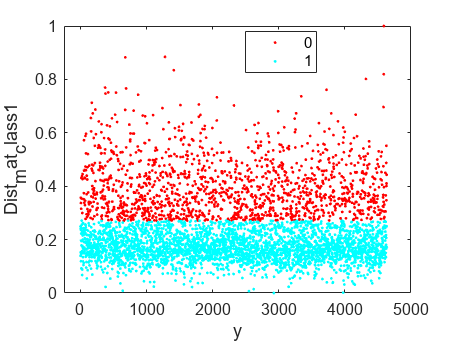

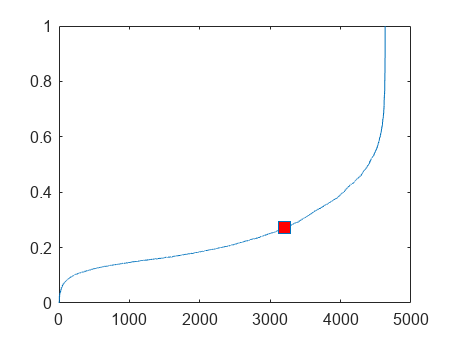

r1 = 1431

threshold_dist_7 = 0.4529

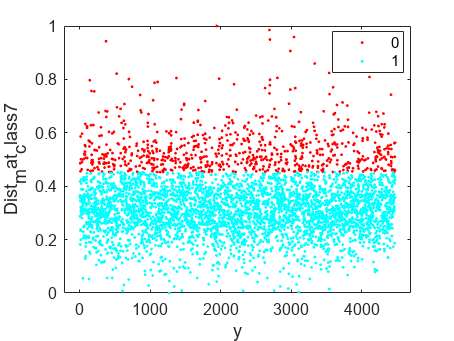

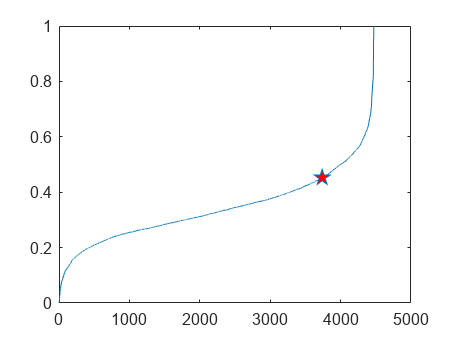

r7 = 734

threshold_dist_1 = 0.2948

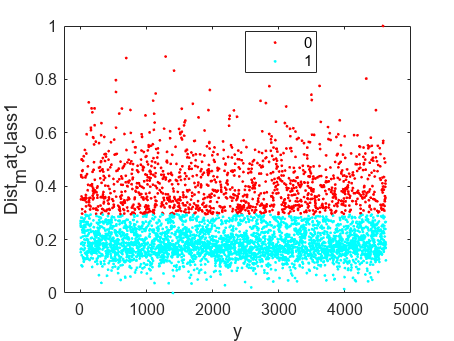

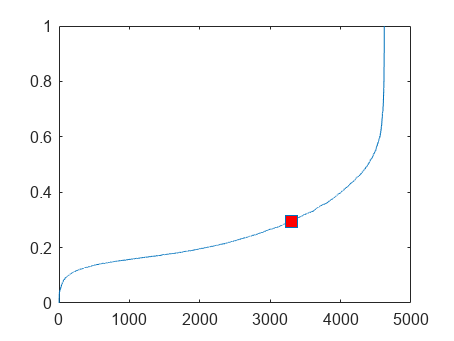

r1 = 1323

threshold_dist_7 = 0.4837

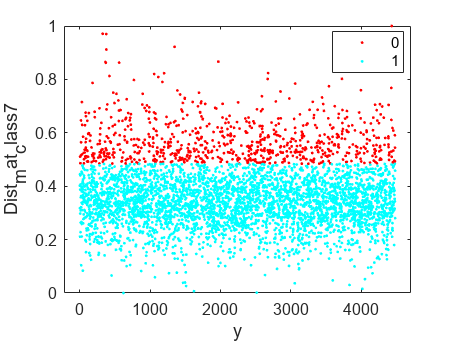

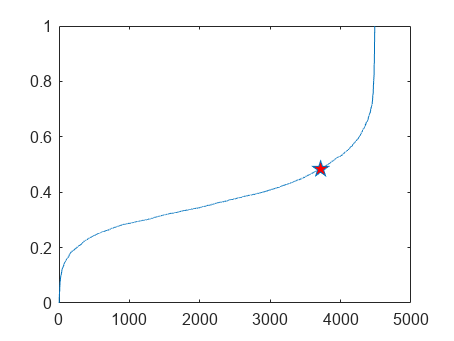

r7 = 769

threshold_dist_1 = 0.3095

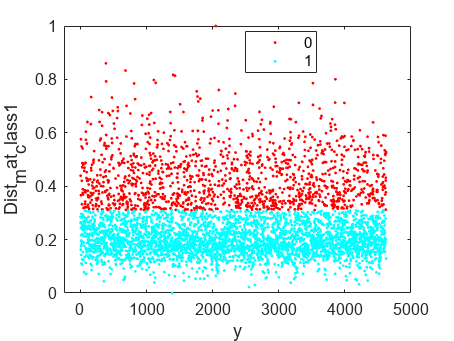

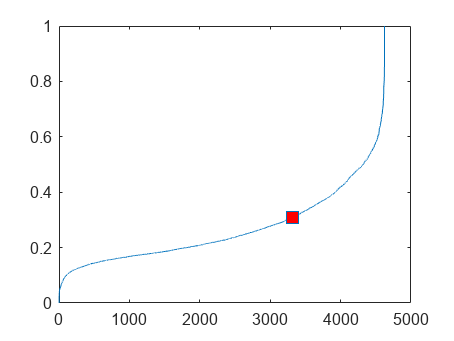

r1 = 1301

threshold_dist_7 = 0.4803

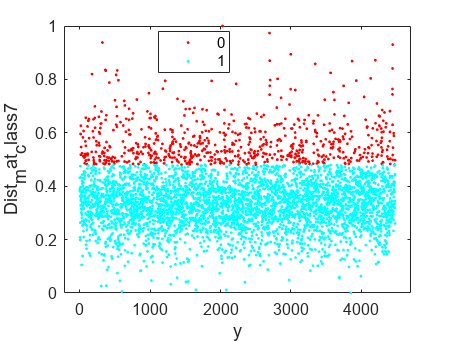

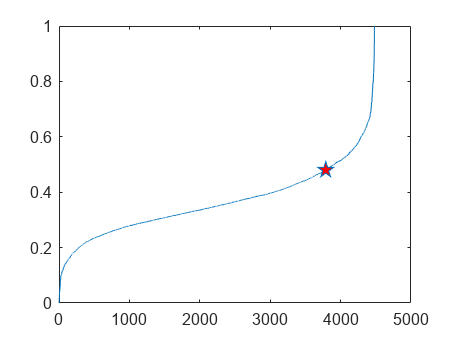

r7 = 692

threshold_dist_1 = 0.3461

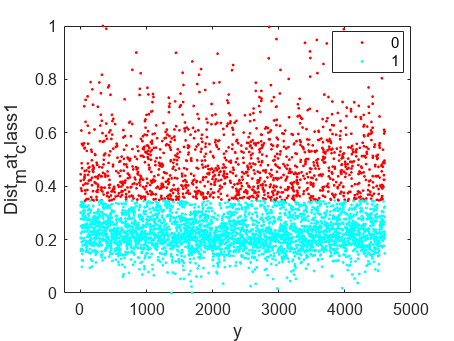

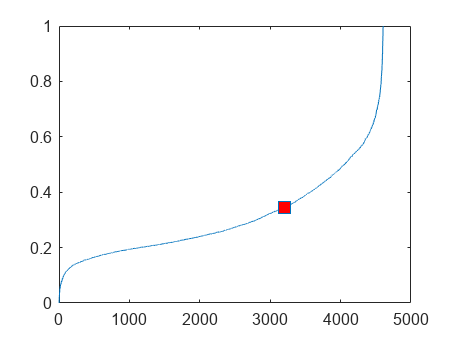

r1 = 1398

threshold_dist_7 = 0.4719

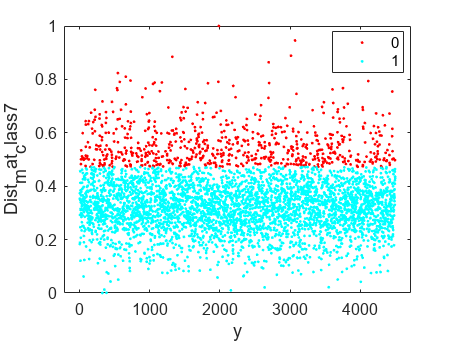

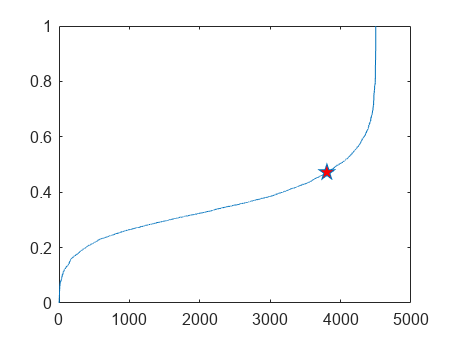

r7 = 695

threshold_dist_1 = 0.2968

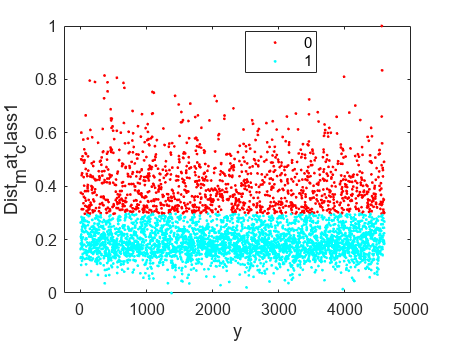

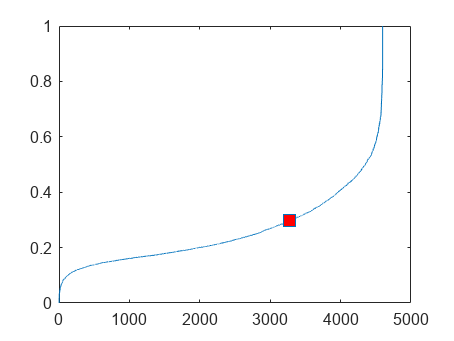

r1 = 1321

threshold_dist_7 = 0.4856

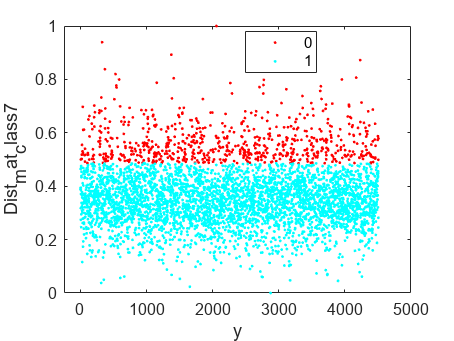

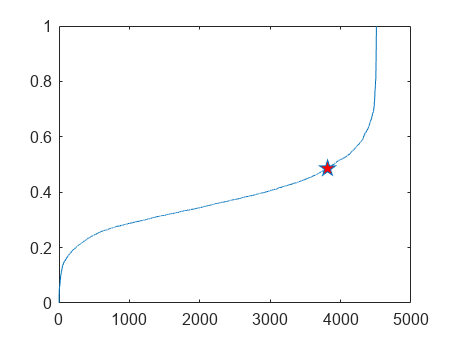

r7 = 693

threshold_dist_1 = 0.3650

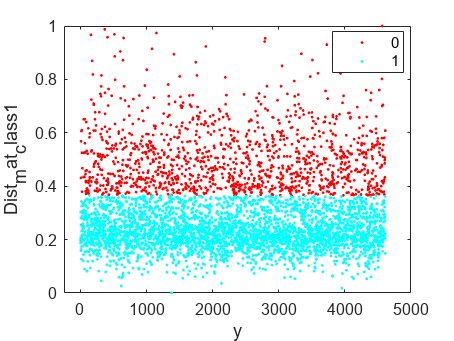

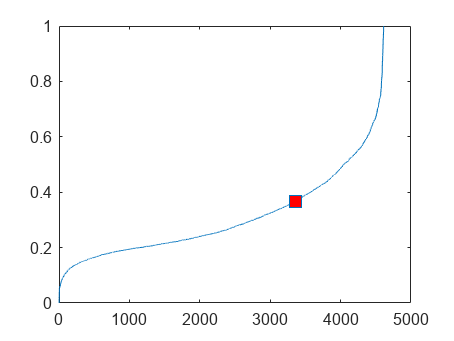

r1 = 1259

threshold_dist_7 = 0.4912

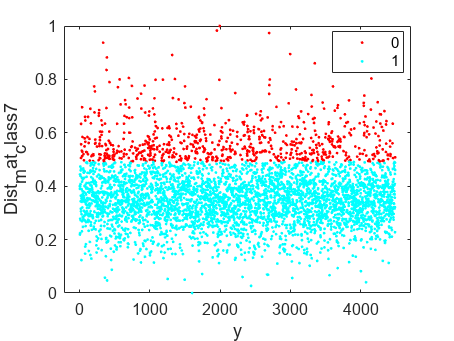

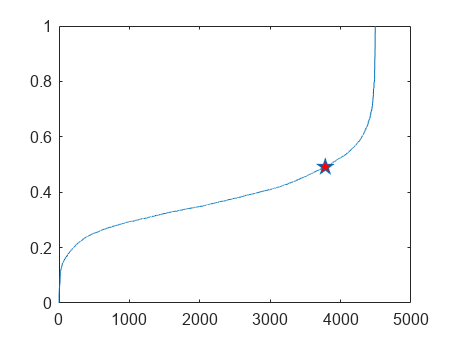

r7 = 710

for j = [1,2,3,4,5,6,7,8,9,10]
    splitfolder=strcat('split',num2str(j));
    M=importdata("C:\Users\shukl\Documents\GitHub\Mnist\split1\per20\mnist_misclass_per_20.csv",",",1);
    per =0;%20%,10,5,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Mnist\
        mkdir (splitfolder)
        cd (splitfolder)
        folder=strcat('per',num2str(percent));
        %         mkdir (folder)
        cd (folder)


        my_file = strcat('mnist_17_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        class1=File(File(:,1)==1,2:785);
        T_class1=class1.';
        T_class1_org=class1.';
        ind_one=find(File(:,1)==1);
        F_class1=[ind_one class1];

        class7=File(File(:,1)==7,2:785);
        T_class7=class7.';
        T_class7_org=class7.';
        ind_seven=find(File(:,1)==7);
        F_class7=[ind_seven class7];
        folder_l1=strcat('ACE_17_dist_knee_l1pca_per',num2str(percent));
        mkdir (folder_l1)

       

        i=1;

        cd C:\Users\shukl\Documents\GitHub\Mnist\

        Dist_mat_class1=[];


        numclass1=length(T_class1);

        T_class1;
        BF_class1=l1pca_BF(T_class1,i,1,100,100,'');
        for k = 1 : numclass1

            A=T_class1(:,k);
            Dist_mat_class1(k)=norm((A-(BF_class1*BF_class1.'*A)),1);
            k;

        end
        Dist_mat_class1;
        min_val=min(Dist_mat_class1,[],"all");
        max_val=max(Dist_mat_class1,[],"all");
        Dist_mat_class1= Dist_mat_class1 -min_val;%]/[max_val-min_val]
        Dist_mat_class1=Dist_mat_class1 /(max_val-min_val);


        Dist_mat_class1;

        [Dist_mat_class1_asc,Indx_1]=sort(Dist_mat_class1,"ascend");

        y_1=(Dist_mat_class1_asc);


        
        [elbow_1,elbow_indx_1]=knee_pt(y_1);


        threshold_dist_1= Dist_mat_class1_asc(elbow_indx_1)
    

        ind_O_1=find(Dist_mat_class1>threshold_dist_1);
        ind_I_1=find(Dist_mat_class1<=threshold_dist_1);
        
        

        
        cluster_1=zeros(size(Dist_mat_class1));
        cluster_1(ind_I_1)=1;
        figure
        y= 1:1:length(class1);
        numGroups = length(unique(cluster_1));
        gscatter(y,Dist_mat_class1,cluster_1,hsv(numGroups))

        figure
        plot(Dist_mat_class1_asc,'-s',"MarkerIndices",(elbow_indx_1),'MarkerFaceColor','red','MarkerSize',10 )

        r1=length(ind_O_1)
        Out_1= T_class1(:,ind_O_1);
        
        T_class1(:,ind_O_1)=[];



        Final_class1=T_class1';

        c1=ones(size(Final_class1,1),1);
        Final_class1=[c1 Final_class1];
        Out_1=Out_1';
        c_1=ones(size(Out_1,1),1);
        Out_1=[c_1 Out_1];



        cd C:\Users\shukl\Documents\GitHub\Mnist\

        Dist_mat_class7=[];


        numclass7=length(T_class7);

        BF_class7=l1pca_BF(T_class7,i,1,100,100,'');
        for k = 1 : numclass7
            A=T_class7_org(:,k);
            Dist_mat_class7(k)=norm((A-(BF_class7*BF_class7.'*A)),1);
            k;

        end
        Dist_mat_class7;
        min_val=min(Dist_mat_class7,[],"all");
        max_val=max(Dist_mat_class7,[],"all");
        Dist_mat_class7= Dist_mat_class7 -min_val;%]/[max_val-min_val]
        Dist_mat_class7=Dist_mat_class7 /(max_val-min_val);

        [Dist_mat_class7_asc,Indx_7]=sort(Dist_mat_class7,"ascend");

        y_7=(Dist_mat_class7_asc);
        
        [elbow_7,elbow_indx_7]=knee_pt(y_7);

        
        threshold_dist_7= Dist_mat_class7_asc(elbow_indx_7)
  

        ind_O_7=find(Dist_mat_class7>threshold_dist_7);
        ind_I_7=find(Dist_mat_class7<=threshold_dist_7);
        
        cluster_7=zeros(size(Dist_mat_class7));
        cluster_7(ind_I_7)=1;
        figure
        y= 1:1:length(class7);
        numGroups = length(unique(cluster_7));
        gscatter(y,Dist_mat_class7,cluster_7,hsv(numGroups))

        figure
        plot(Dist_mat_class7_asc,'-p',"MarkerIndices",(elbow_indx_7),'MarkerFaceColor','red','MarkerSize',10 )

        r7=length(ind_O_7)
       
        Out_7=T_class7(:,ind_O_7);
        T_class7(:,ind_O_7)=[];



        Final_class7=T_class7';

        c2=7*ones(size(Final_class7,1),1);
        Final_class7=[c2 Final_class7];
        Out_7=Out_7';
        c_2=7*ones(size(Out_7,1),1);
        Out_7=[c_2 Out_7];

        cd C:\Users\shukl\Documents\GitHub\Mnist\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_class1.',Final_class7.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:785)=  M.colheaders;
        filel1pca=strcat('mnist_17_misclass_per',num2str(percent),'_ACE_l1pca_',num2str(i),'.csv');
        writetable(L1pca_file,filel1pca);

        T1 = array2table(Out_1);
        T1.Properties.VariableNames(1:785)= M.colheaders;
        one_file = strcat('Out1_mnist_17_misclass_per_',num2str(percent),'.csv');
        writetable(T1,one_file);

        T7 = array2table(Out_7);
        T7.Properties.VariableNames(1:785)= M.colheaders;
        seven_file = strcat('Out7_mnist_17_misclass_per_',num2str(percent),'.csv');
        writetable(T7,seven_file);


    end
end